# 回波

### 参考文献：一种水下多亮点目标模拟器的设计 宋绪栋,刘鹏仲

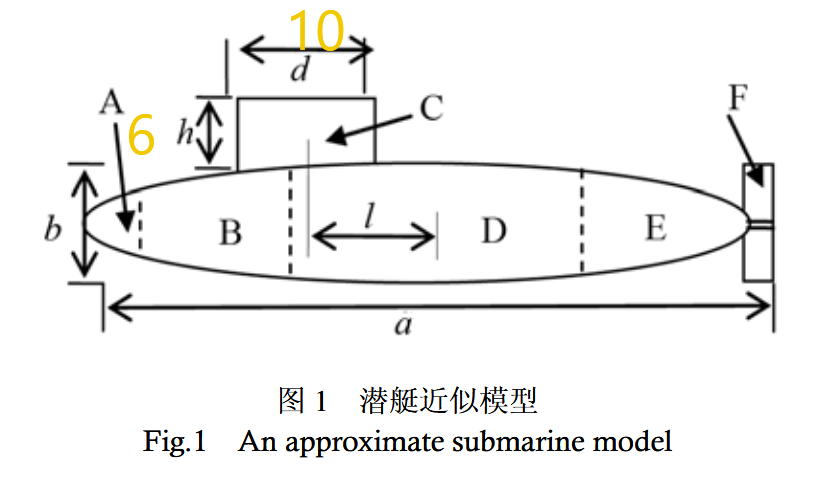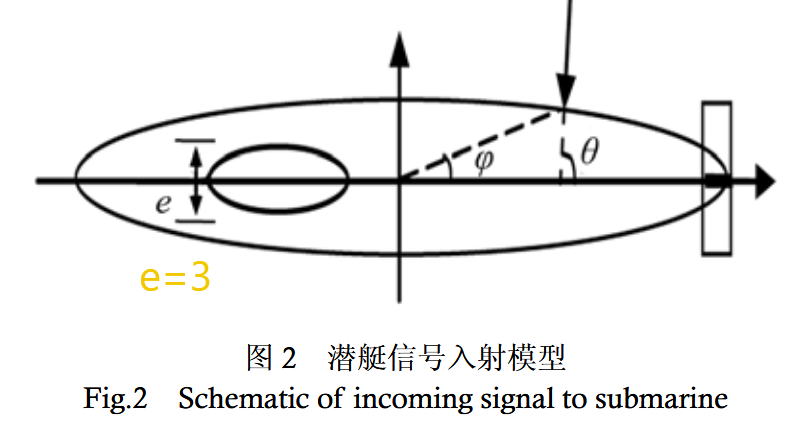

clc;clear;close all;
a = 70 ;    %a表示潜艇长轴
b = 6 ;    %b表示潜艇短轴
c = 1500;
r = 200;%离潜艇中心点 200 m 处
%theta = linspace(1,180,180);
theta = 45;

阵元A的发射参数：

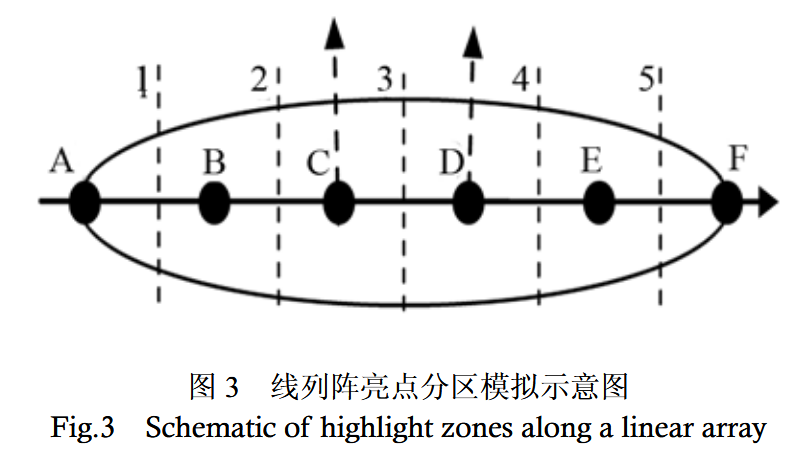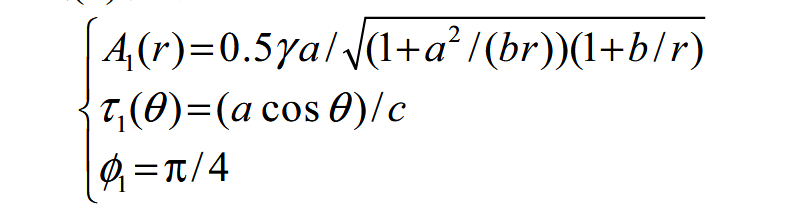

%阵元A的参数
A1 = 0.4*0.2* a/sqrt(  (1+a.*a./(b*r))*(1+b/r) );
tau1 = a.*cos(theta*pi/180)/c;
phi1 = pi/4;

阵元C（舰桥）:

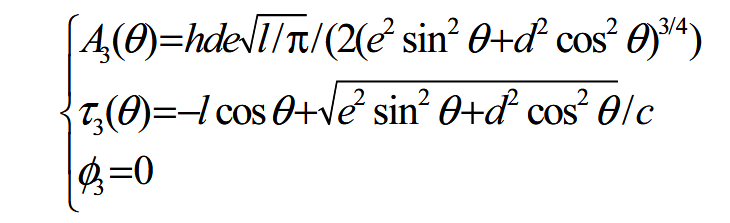

%阵元C
h = 6;d = 10;e = 3;
l = 10;%舰桥中心与 艇体中心相距 10 m
A3 = h*d*e*sqrt(l/pi)./(2* (e.^2 .* (sin(theta*pi/180).^2) + d.^2.*(cos(theta*pi/180).^2)).^(3/4)  );
tau3 = (l.*cos(theta*pi/180) + sqrt(e.^2 .* (sin(theta*pi/180).^2) + d.^2 .* (cos(theta*pi/180).^2)) )/ c;
phi3 = 0;

阵元B、D、E:

对于大面积光滑曲面：

R1和R2是镜反射点出的两个曲面半径，r是到反射点的距离，在十分远处，可表示为：

潜艇主干部分的亮点参数如下：

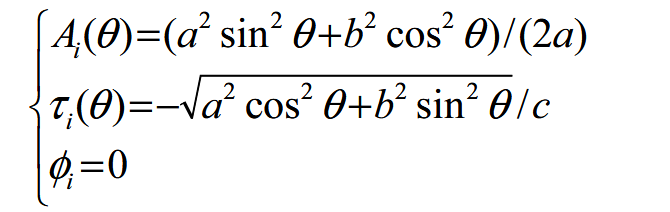


%阵元B、D、E
A2 = (a.^2.*(sin(theta*pi/180).^2)  + b.^2.*(cos(theta*pi/180).^2) )/2*a;
tau2 = -sqrt(a.^2.*(cos(theta*pi/180).^2) + b.^2.*(sin(theta*pi/180).^2))/c;
phi2 = 0;

A4 = (a.^2.*(sin(theta*pi/180).^2)  + b.^2.*(cos(theta*pi/180).^2) )/2*a;
tau4 = -sqrt(a.^2.*(cos(theta*pi/180).^2)+ b.^2.*(sin(theta*pi/180).^2))/c;
phi4 = 0;

A5 = (a.^2.*(sin(theta*pi/180).^2)  + b.^2.*(cos(theta*pi/180).^2) )/2*a;
tau5 = -sqrt(a.^2.*(cos(theta*pi/180).^2)+ b.^2.*(sin(theta*pi/180).^2))/c;
phi5 = 0;

阵元F：

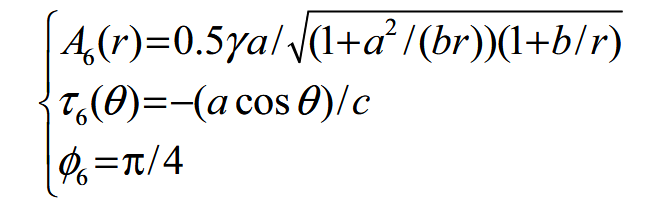

%阵元F
A6 = 0.4*0.2* a/sqrt(  (1+a.*a./(b*r))*(1+b/r) );
tau6 = -a.*cos(theta*pi/180)/c;
phi6 = pi/4;

设置CW脉冲信号：

在离潜艇中心点 200 m 处发射 CW 脉冲信号,信号频率为 30 kHz,脉宽为 1.25 ms

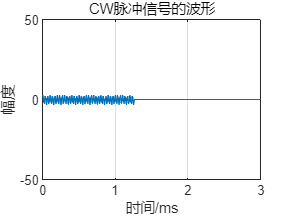

%% 信号频率为 30 kHz,脉宽为 1.25 ms的CW信号
% 定义参数
fs = 100000; % 采样频率，可根据需要调整，这里设置为100kHz
t = 0:1/fs:1.25e-3; % 时间向量，对应脉宽1.25ms
fc = 30000; % 信号频率为30kHz

t_scale = 0:1/fs:0.2-1/fs;

% 生成CW脉冲信号
cw_pulse = 3*cos(2*pi*fc*t);
cw_pulse = [cw_pulse zeros(1,length(t_scale)-length(t))];
% 绘制信号波形
figure
plot(t_scale*1000, cw_pulse);
xlabel('时间/ms');ylabel('幅度');title('CW脉冲信号的波形');grid on;axis([0,3,-50,50]);

回波信号

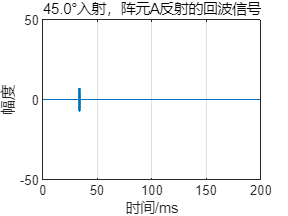

%阵元A
delay1_n = round(tau1/(1/fs)); %亮点A造成的延迟
CW_1 = A1.*3*cos(2*pi*fc*t+phi1);%亮点A造成的幅度变化
CW_1 = [zeros(1,delay1_n) , CW_1, zeros(1,length(t_scale)-length(t)-delay1_n)];
figure
plot(t_scale*1000, CW_1);
xlabel('时间/ms');ylabel('幅度');title(sprintf('%.1f°入射，阵元A反射的回波信号', theta)); 
grid on;axis([0,200,-50,50]);

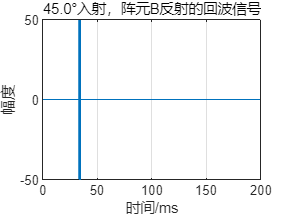

%阵元B
delay2_n = round(tau2/(1/fs)); %亮点B造成的延迟
CW_2 = A2.*3.*cos(2*pi*fc*t+phi2);%亮点B造成的幅度变化
CW_2 = [zeros(1,abs(delay2_n)) , CW_2, zeros(1,length(t_scale)-length(t)-abs(delay2_n))];
figure
plot(t_scale*1000, CW_2);
xlabel('时间/ms');ylabel('幅度');title(sprintf('%.1f°入射，阵元B反射的回波信号', theta)); 
grid on;axis([0,200,-50,50]);

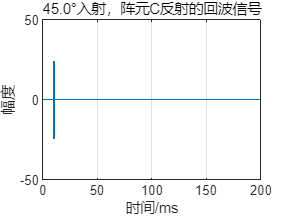

%阵元C
delay3_n = round(tau3/(1/fs)); 
CW_3 = A3.*3.*cos(2*pi*fc*t+phi3);
CW_3 = [zeros(1,delay3_n) , CW_3, zeros(1,length(t_scale)-length(t)-delay3_n)];
figure
plot(t_scale*1000, CW_3);
xlabel('时间/ms');ylabel('幅度');title(sprintf('%.1f°入射，阵元C反射的回波信号', theta)); 
grid on;axis([0,200,-50,50]);

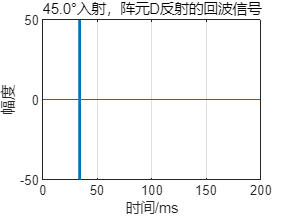

%阵元D
delay4_n = round(tau4/(1/fs)); 
CW_4 = A4.*3.*cos(2*pi*fc*t+phi4);
CW_4 = [zeros(1,abs(delay4_n)) , CW_4, zeros(1,length(t_scale)-length(t)-abs(delay4_n))];

figure
plot(t_scale*1000, CW_4);
xlabel('时间/ms');ylabel('幅度');title(sprintf('%.1f°入射，阵元D反射的回波信号', theta)); 
grid on;axis([0,200,-50,50]);

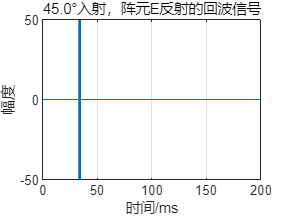

%阵元E
delay5_n = round(tau5/(1/fs)); 
CW_5 = A5.*3.*cos(2*pi*fc*t+phi5);
CW_5 = [zeros(1,abs(delay5_n)) , CW_5, zeros(1,length(t_scale)-length(t)-abs(delay5_n))];

figure
plot(t_scale*1000, CW_5);
xlabel('时间/ms');ylabel('幅度');title(sprintf('%.1f°入射，阵元E反射的回波信号', theta)); 
grid on;axis([0,200,-50,50]);

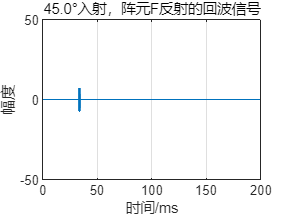

%阵元F
delay6_n = round(tau6/(1/fs)); 
CW_6 = A6.*3.*cos(2*pi*fc*t+phi6);
CW_6 = [zeros(1,abs(delay6_n)) , CW_6, zeros(1,length(t_scale)-length(t)-abs(delay6_n))];

figure
plot(t_scale*1000, CW_6);
xlabel('时间/ms');ylabel('幅度');title(sprintf('%.1f°入射，阵元F反射的回波信号', theta)); 
grid on;axis([0,200,-50,50]);

## 此处有问题

45°时，舰尾亮点、舰体亮点、 舰桥亮点和舰艏亮点起作用,此时舰体的移动亮点在阵元 E 附近

将各个阵元的相加

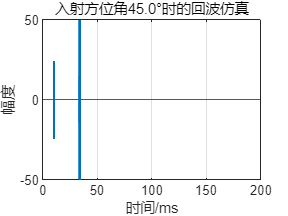

reflectSig = CW_1+CW_5+CW_3+CW_6;
figure
plot(t_scale*1000, reflectSig);
xlabel('时间/ms');ylabel('幅度');title(sprintf('入射方位角%.1f°时的回波仿真', theta)); 
grid on;axis([0,200,-50,50]);

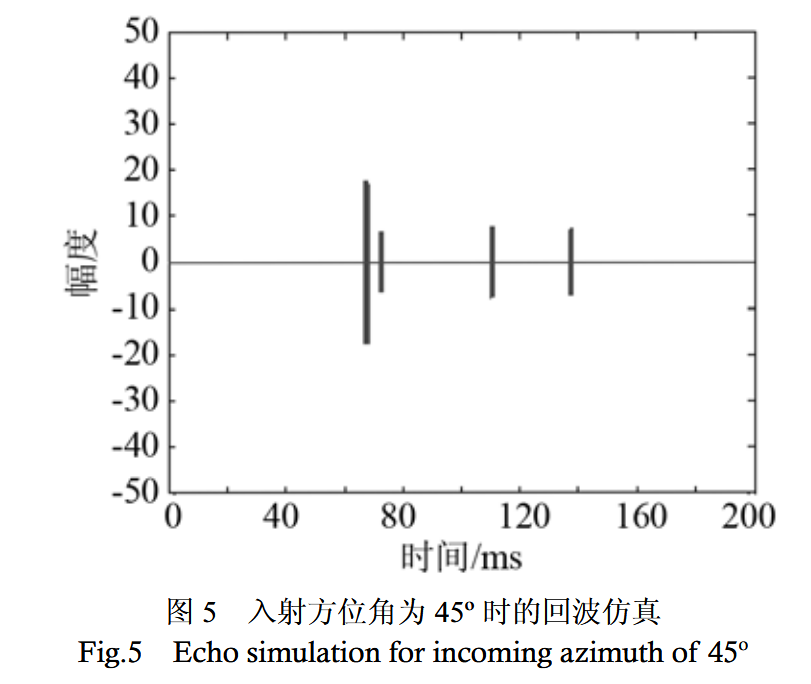

**设艇体参数为 a =70 m、b =6 m,当 0° <θ<87.9° 时,式(8)为发射阵元E的参数;**

**当 87.9° <θ≤90° 时, 式(8)为发射阵元 D 的参数;**

**当  90° <θ<92.1° 时,该 移动亮点的能量应叠加在发射阵元 C 上;**

**当  92.1° ≤θ<180° 时,式(8)为发射阵元 B 的参数;**

**另外,设定θ=0, π 时,艇体移动亮点被舰艏或舰尾遮蔽而不予以考虑。**

if theta<=87.9
CWReflect = CW_1+CW_5+CW_6;
elseif 87.9<theta<=90

elseif 90<theta<=92.1

elseif 92.1<theta<=180

end




